# MatLab Workshop

An introductory course into MatLab.

Disable warnings and errors that arise throughout the script.

clear;
%#ok<*HIST,*PLOTYY,*NASGU,*ASGLU,*UNRCH,*DEFNU,*EZPLT,*LBODUP>

## Table of Contents

## 1 Introduction

MatLab is a numerical computing environment and programming language, developed from Mathworks® since 1984. It can be used (among others) for simple algebra, to solve linear (differential) equations, to numerically approximate nonlinear problems, graphical and sound output, real-time signal processing and machine learning tasks.

**Applications: **computation on digital (medical) data from sensors (e.g. EEG, ECG, microphones or cameras), execution of de-noising or artifact suppresion algorithms, to visualize data or design 3-dimensional models of bones, prostheses, physiological structures).

### 1.1 Getting started

**The command window **is the central window of MatLab. Input MatLab commands line-by-line and see the output. Output can be suppressed with a semicolon ”;” at the end of the line. Old commands re-appear with “Arrow-up” key.

**The command history**: chronological order of the previously used commands. Mark commands here and use “F9” (Windows) or “SHIFT-F7” (Mac) to execute this command again.

**Workspace**: All defined variables are listed here with “name” and “value”, rightclick on “name” offers to show more categories.

**Editor**: The editor allows editing, saving and using MATLAB scripts and functions. Key words are highlighted using color.

**Self-written programs must be located in folders that can be found by MatLab, **otherwise MATLAB responds with ”Undefined function or variable”.

- Search paths can be viewed and edited via “Set Path”

- Make the folder that contains all your self-written programs as the current directory. MATLAB always looks first in the current directory for programs to execute.

### 1.2 MatLab Scripts

Scripts are collections of commands that could be copied line-by-line into the command window and be executed one-by-one. Save scripts as `.m`-File and execute the script by calling its name in the command window (without the .m).

- Sections of the script can be executed separately by marking it with the cursor (or pressing CTRL-A for marking all) and hitting “F9” (marked code is executed)

- If a program breaks down and MATLAB is no longer usable, the key combination “CTRL-C” kills the current program and returns to the idle command window.

- *Paths and file names should be “websafe”: no umlaut, no space and no special characters except for ‘_’, never start with a digit.*

## 2 Data Types

### 2.1 Vectors

Vectors are the main working data structure in MATLAB. They are a linear collection of elements which can contain characters or numbers. They come either as row or as column vectors, or as both (also known as matrices). A vector can be created and stored in a single variable by using square brackets to signal the beginning and end of the vector and using either spaces or commas (same outcome) or semicolons.

[1 3 5 7 9]

ans =      1     3     5     7     9


or

[1, 3, 5, 7, 9]

ans =      1     3     5     7     9


A second method of creating a vector is to use the ’:’ operator. The general structure is given by:

`    vector = start : interval : end`

Where the interval is the dierence between elements in the array. If an interval is not specified, the default interval is 1.

1:9

ans =      1     2     3     4     5     6     7     8     9


1:2:9

ans =      1     3     5     7     9


#### 2.1.1 Linspace

As opposed to stating the interval between two vector elements, it is possible to state the number of elements between start and end by using the function linspace. The general form of this command is:

    `linspace(start, end, n)`

This will generate n equispaced elements between the start and end variable, inclusive.

linspace(1, 10, 5)

ans =     1.0000    3.2500    5.5000    7.7500   10.0000


#### 2.1.2 Row and column vectors

The vectors so far have all been created as row vectors. This means that the elements in the vector are aligned as a single row. Alternatively, it is possible to also create column vectors by separating each single element with the semicolon ’;’ operator:

[1; 3; 5; 7; 9]

ans =      1
     3
     5
     7
     9


#### 2.1.3 Indexing vectors

Indexing is the process of looking at or extracting a specified element in a vector or array. Individual or groups of elements can be indexed. Indexing occurs by using the round brackets () with an integer number. Note that MATLAB starts indexing at 1. Other programming languages like Python start indexing the first element with 0.

a = [1 3 5 7 9];

a(2) % returns the 2nd element

ans = 3

a(2:4) % returns the 2nd to 4th elements

ans =      3     5     7


a(2:end) % end is a keyword indicating the last element

ans =      3     5     7     9


### 2.2 Characters

Similar to a series of numbers that can be stored in a variable, a string of characters can also be saved in a variable. To dierentiate between a character string and a variable, the string must be surrounded by apostrophes i.e. ’ ’ . Everything within the apostrophes will be stored in a separate element, including spaces. Indexing through the character string is similar to indexing a vector. Note that MATLAB is **case sensitive**. Storing a = ’foo’ is not the same as b = ’Foo’.

a = 'What a lovely string';
a(1:5)

ans = 'What '

It is also possible to use an index vector to extract a specific assortments of elements:

a = 'What a lovely string';
indexvec = 1:2:13;
a(indexvec)

ans = 'Wa  oey'

## 3 Basic Functions

### 3.1 Basic math operators

All math operators in MATLAB use the same rules for vector and matrix operations (e.g., for the multiplication of two vectors, ˛x and ˛y, the number of elements in the row of x must be the same as the number of elements in the column of ˛y ). Similarly for adding and subtraction, the number of elements of each vector must match.

a = [1 3 5 7 9];
b = [2 4 6 8 10];

**Addition**

a + b

ans =      3     7    11    15    19


**Subtraction**

a - b

ans =     -1    -1    -1    -1    -1


**Multiplication**

a(1) * b(1)

ans = 2

**Left Division**

a(1) / b(1)

ans = 0.5000

**Right Division**

a(1) \ b(1)

ans = 2

**Exponent**

b(1)^2 

ans = 4

### 3.2 Element specific operator

In the preceding section, each vector was being processed as vector calculus suggests. But what if you would like to treat each element of the vector individually? In such cases you need to use the ’.’ operator! You can think of the dot-operator as being ’elementwise’ calculations.

a = [1 3 5 7 9];

a.^2

ans =      1     9    25    49    81


a.*2

ans =      2     6    10    14    18


a./0.1

ans =     10    30    50    70    90


### 3.3 Common built-in mathematical functions

As MATLAB is a high-level computing language, there are numerous built-in functions that are readily available; they just need to be found and learned how to be used. Some of the most commonly used trigonometric related functions are:

`    pi, sin(x), cos(x), tan(x), asin(x), acos(x), atan(x)`

Using these functions, the data inputted or outputted will be in radians. If you would like to have input or output in degrees, just attach a ’d’ to the respective function name:

`    sind(x), cosd(x), tand(x), asind(x), acosd(x), atand(x)`

Other commonly used functions are:

`    sqrt(x), exp(x), log(x), log10(x), abs(x)`

Note: `exp(x)` and `log(x)` represents the natural exponential and logarithm respectively. This means that `exp(x)` is the same as e^x, and `log(x)` is the same as log_e(x) or ln(x).

sin(pi / 2)

ans = 1

sind(270)

ans = -1

asin(1)

ans = 1.5708

### 3.4 Rounding

There are multiple ways for rounding data in MATLAB. The following are the most common methods for rounding:

- `round(x)` - Rounds the vector x to the nearest integer

- `floor(x)` - Rounds the vector x down, to the nearest integer towards -infinity

- `ceil(x)` - Rounds the vector x up, to the nearest integer towards infinity

- `fix(x)` - Rounds the vector x to the nearest integer towards zero

x = [-3.1416, 1.5718, 3.1416];

round(x)

ans =     -3     2     3


floor(x)

ans =     -4     1     3


ceil(x)

ans =     -3     2     4


fix(x)

ans =     -3     1     3


Unfortunately, these functions only round to the integer, no decimal value is maintained. If rounding with decimal places is needed, the round command accepts the number of decimal places as a second argument. Alternatively, the following workaround can be used:

x = pi;

round(x, 2)

ans = 3.1400

round(x * 100) / 100

ans = 3.1400

### 3.5 Sum Functions

When the function `sum(x)` is applied to the vector `x`, it will add up all its elements. By default (without additional input arguments), the sum function will add up all the elements in the row, though it is also possible to sum up all the elements in the columns. To change the default, a second argument can be added to the function to force a particular dimension.

    `sum(x, dimension)`

The dimension can be denoted by using either 1 (summing in the columns), or 2 (summing in the rows). Similar to the `sum` function is the `prod` function. It creates the product (i.e., multiplication) of all the elements of its argument.

x = [-3.1416, 1.5718, 3.1416];

sum(x)

ans = 1.5718

sum(x,1)

ans =    -3.1416    1.5718    3.1416


sum(x,2)

ans = 1.5718

### 3.6 Max and Min function

As the name suggests, the `max` and `min` function provides the maximum and minimum values of a vector. Although knowing just the maximum value in the vector may be sucient, most of the time it is just as important to know the location of the maximum value. This can be done by storing the values into two variables as follows

    `[number, loc] = max(vector)`

Similar to the sum function, the dimension across the minimum or maximum is being computed can be specified as a second argument.

x = [1, 2, 3, 4, 3, 2, 1];

[maximum, ~] = max(x)

maximum = 4

[minimum, loc] = min(x)

minimum = 1

loc = 1

### 3.7 Random Number Generator

There are two random number generator; `rand` and `randn`. Both of these commands produce random variables, however, their distribution diers:

- `rand` produces random variables in the interval [0, 1] with **equal distribution**

- `randn` produces random variables with a **normal distribution** with mean value 0 and standard deviation 1

Both functions will produce a random decimal number with 4 significant digits. The `rand(m,n)` produces an m x n matrix of random numbers, each of which is ranging between 0 to 1.

rand

ans = 0.1251

rand(2,2)

ans =     0.2825    0.0865
    0.0855    0.3943


Calling the random function repeatedly will result in a dierent answer every time. This is very useful for simulating probabilities. For example, if we wanted to simulate the throws of a dice, we would use the random number generator with the rand command giving equal distribution. However, the `rand` function only returns a value between 0 and 1, and a dice only has numbers between 1 to 6. In order to return the proper values, the random number must be multiplied by 6 added by 1 then rounded down such that it only returns integers between 1 to 6. Alternatively, the command `randi` outputs integer values between 1 and the input argument’s value with equal distribution.

floor(1 + 6 * rand)

ans = 4

randi(6)

ans = 4

Note that MATLAB only can generate *pseudo-random values*. This means that the distribution of values is in fact random and in agreement with either the equal distribution or the normal distribution. However, their exact values are deterministic. You can see this when you do the following: Close MATLAB and open it again and input as the first command `rand`. You will get a specific number. Note this number down. Close MATLAB again and open it again and input as the first command `rand`. You will get exactly the same number! MATLAB can only generate the same sequence of numbers if you do not specify that it should start at a specific (random) point in this sequence of numbers that it recalls. This start point is in MATLAB called the ¨seed¨. If you give MATLAB the command `rng(’shuffle’)` before executing the `rand` command (or any other command generating random numbers), you will randomize this seed based on the current time and you will get ’actual’ random numbers.

rng('shuffle')
rand()

ans = 0.5381

### 3.8 Specific vector and number generation commands

MATLAB oers a few specific commands to easily create simple vectors. These are

- `zeros` - creates a vector made out of zeros 

- `ones` - creates a vector made out of ones 

- `nan` - ’NaN’ stands for ¨Not-a-number¨, which is MATLABs way of saying that it cannot calculate that specific number (for example the result of a division by 0). The command nan with round brackets can also be used to create a vector of NaNs. 

- `i` - imaginary number. When using this, MATLAB changes the respective variable to a ¨complex¨ datatype. 

- `j` - imaginary number. MATLAB doesn’t care if you better like the engineering notation ’j’ for the imaginary number or more the mathematician/physicist notation ’i’.

### 3.9 Transforming row to column vectors (and vice versa)

We already got to know how to create row and column vectors. Sometimes it is necessary to transform a row to a column vector. This can easily be done by the `.’` operator, i.e. a dot followed by a vertical apostrophe. It can be remembered as the **¨transposition¨** operation. The single apostrophe operator delivers in the case of real-valued vectors the same results. For complex vectors (i.e., vectors who at least have a single element containing an imaginary part), it will transpose and complex conjugate.

a = [1 3 5 7 9];

% transposition
a = a.' 

a =      1
     3
     5
     7
     9


% assign complex number to 2nd element
a(2) = 1 + 1i; 

% complex conjugte
a' 

ans =    1.0000 + 0.0000i   1.0000 - 1.0000i   5.0000 + 0.0000i   7.0000 + 0.0000i   9.0000 + 0.0000i


An easy way of forcing a vector to become a column vector - even if you don’t exactly know whether your data vector comes originally as row or as column vector is to use the (:) as input argument.

a = [1 3 5 7 9];

% This makes a row to a column vector
a = a(:)

a =      1
     3
     5
     7
     9


% Now the column vector is kept as a column
a = a(:)

a =      1
     3
     5
     7
     9


### 3.10 Scalar Product

The scalar product of two vectors can be computed in two dierent ways. Either use the command `dot`, or use the operator ’`*`’. When using the operator ’`*`’ it is important to pay attention to the dimensions of the vectors. The vector left of the `*` needs to be a row vector and the vector to the right needs to be a column vector. We will see later that this generalizes to the matrix product notation: The number of columns of the matrix left to the operator needs to match to the number of rows to the right of the operator.

a = [1 3 5 7 9];
b = [2 4 6 8 10];

% scalar product
a * b.'

ans = 190

% here a transposition is not needed
dot(a, b)

ans = 190

### 3.11 Modulus and Remainder

The `mod` function is the modulus after division, also know as the *¨rest after division¨*. However this function should not be confused with the remainder function, `rem`. The modulus function will only provide the absolute value of the remainder after division, i.e., the sign of the original input will be lost. In contrast, the `rem` function will preserve the sign of the original input.

x = 10;
y = 3;

mod(x, y)

ans = 1

mod(-x, y)

ans = 2

rem(-x, y)

ans = -1

## 4 Matrices

Matrices are the generalization of the data type vector. Just as in algebra, a matrix is a rectangular set of numbers, where each entry is called an element. In general: an n x m matrix consists of n rows and m columns.

Note that the first index of an element denotes always the row number and the second always the column number. This is the exact same notation that MATLAB also uses and should be remembered. In order to generate a matrix in MATLAB, combine the rules that are known from generation of row and column vectors: A comma between two elements denotes that they come in the same row, whereas a semicolon denotes the beginning of a new row.

A = [1, 2, 3; 4, 5, 6; 7, 8, 9] 

A =      1     2     3
     4     5     6
     7     8     9


The already known commands for generating vectors can be generalized for creating matrices:

- `zeros(n,m)` - creates an n x m matrix made out of zeros 

- `ones(n,m)` - creates an n x m matrix made out of ones 

- `nan(n,m)` - creates an n x m matrix made out of NaNs

- `eye(n)` - creates an n x n **identity** matrix 

- `magic(n)` - creates an n x n **magical** matrix

MATLAB is not restricted to 2-dimensional matrices, but can deal with even more dimensions. For example `ones(n,m,p)` will create an n x m x p matrix (i.e., 3- dimensional).

### 4.1 Indexing matrices

#### 4.1.1 Row-column indexing

Similar to indexing vectors, a set of integer numbers is used to index matrices. Each number hereby represents one dimension. By convention, when indexing matrices, the first number represents the row and the second the column. It is possible to index more than just one element at a time; an entire column or row can be returned by using ’`:`’ (colon) instead of a number. This is called row-column-indexing.

A = magic(3);

% get the specified element
A(2,3)

ans = 7

% choose the entire 1st row
A(1, :)

ans =      8     1     6



A = magic(7);

% choose the 1st, 3rd and 5th row
A(1:2:5, :)

ans =     30    39    48     1    10    19    28
    46     6     8    17    26    35    37
    13    15    24    33    42    44     4


% choose the 1st, 4th and 7th column
A(:, 1:3:7)

ans =     30     1    28
    38     9    29
    46    17    37
     5    25    45
    13    33     4
    21    41    12
    22    49    20


% choose the 4 last rows
A(end-3:end, :)

ans =      5    14    16    25    34    36    45
    13    15    24    33    42    44     4
    21    23    32    41    43     3    12
    22    31    40    49     2    11    20


% 4th, 6th and 1st column (in this order)
A(:, [4 6 1])

ans =      1    19    30
     9    27    38
    17    35    46
    25    36     5
    33    44    13
    41     3    21
    49    11    22


It may be at first glance confusing when to use square brackets and when to use round brackets. In general, indexing a matrix (and also vectors) requires round brackets, as the top five commands show. Square brackets are only used whenever several elements in a matrix should be indexed at once. The square brackets therefore denote a separate ’index vector’ that specifies the (several) positions that you would like to extract from that matrix. The output is a matrix with optimally few dimensions. If a matrix gets assigned to an existing matrix the elements requiring the selected matrix will be overwritten (without notice!). Elements outside of the range of the output matrix are preserved.

#### 4.1.2 Linear indexing

There is a second possibility to address the different matrix elements and therefore to have access to each one of them individually. This works by assigning only one integer number in round brackets to the matrix variable and is called linear indexing. MATLAB interprets this as the element which is present when stock-piling each column on top of each other starting from the left-most column. In other words: MATLAB goes vertically through the rows. This has the advantage that only a single number is needed to uniquely identifying an element.

One of the most common errors that you will encounter in MATLAB is that MATLAB is trying to index values outside of the dimension range.

    `??? Index exceeds matrix dimensions.`

This error can occur when using any index notation. In order to resolve this, it is necessary to check the dimensions of the variables in the workspace and make sure that MATLAB doesn’t try to use higher number than the dimensions of the respective matrix, which can be obtained with

    `[numrows, numcol] = size(A)`

The first output argument hereby denotes the number of rows, the second the number of columns. If you need to write a matrix as a "stacked" column vector (just as the linear indexing notation is), you can use the already known colon ’`:`’ operator. A backtransformation can be made using the command `reshape`. Also here (as always), the first argument denotes the number of desired rows, the second the desired columns.

A = magic(3);

A = A(:)

A =      8
     3
     4
     1
     5
     9
     6
     7
     2


A = reshape(A, 3, 3)

A =      8     1     6
     3     5     7
     4     9     2


How to get a linear index if the matrix dimensions are large or unknown? `sub2ind` provides a linear index from multiple subscripts (i.e., from the row-column notation) The inverse is the command `ind2sub`.

A = randn(45, 28);
linindex = sub2ind(size(A), 3, 6)

linindex = 228

[row, col] = ind2sub(size(A), 228) 

row = 3

col = 6

#### 4.1.3 Logical indexing

The last way to index a matrix may be even the most powerful one if it is wisely used. It is called the *’logical indexing’* notation. Some of the most common reasons for using matrices is to store data and data-mining/manipulation. A logical expression can be used as an argument to find elements fulfilling this expression:

    `find(matrix booleanOperator threshold)`

The result of this function is the linear index value of each of the elements within the matrix for which the logical expression is true.

A = magic(3);

% find all indices where matrix element is > 5
indexval = find(A > 5)

indexval =      1
     6
     7
     8


How does that work in detail? In general, the expression

    `find(matrix booleanOperator threshold)`

compares each single element of the matrix with the threshold value according to the boolean Operator and creates a new matrix of the same dimensions as the original matrix. However, the output matrix is a logical matrix where each element is either ’`TRUE`’ (=1) or ’`FALSE`’ (=0). You can directly see this matrix by using this as a command (i.e., without the find command. However, this logical matrix is then the input to the find command, and the find command finds the index positions of those elements that are different from 0. This means that only those positions are returned where the logical expression is ’`TRUE`’.

If two outputs are assigned, the command `find` will give out row and column number of each element that fulfills the logical expression, i.e., it switches to the row-column indexing notation.

% find all indices where matrix element is > 5
[row, col] = find(A > 5)

row =      1
     3
     1
     2


col =      1
     2
     3
     3


Logical expressions include bigger/smaller comparisons with ’`>`’, ’`<`’, ’`>=`’, ’`<=`’, comparisons on equality with ’`==`’, ’`=`’ as well as ’`&`’ (AND), ’`|`’ (OR), ’`~`’ (NOT).

### 4.2 Matrix concatenation

Matrix concatenation is the process of joining small matrices into a single large matrix. The concatenation operator is symbolized by the square brackets ’`[]`’. This is the same operator as for generating vectors or matrices, because also for generating vectors and matrices we are basically concatenating numbers (or vectors) to a matrix. Important here is: The dimensons of the matrices being concatenated must match:

- If matrices are concatenated to the rows then the number of columns needs to match.

- If matrices are concatenated to the columns then the number of rows needs to match.

If the columns or rows do not match, an error similar to the following occurs:

`    ??? Error using ==> vertcat `

`    CAT arguments dimensions are not consistent.`

Hereby, the already known rules from vector concatenation apply: 

- A space or a comma indicates that the following matrix is concatenated horizontally to the right (new column)

- A semicolon indicates that the following matrix is concatenated vertically to the bottom (new row)

A = magic(3);
B = magic(3);

% matrix B is concatenated below matrix A
C = [A; B]

C =      8     1     6
     3     5     7
     4     9     2
     8     1     6
     3     5     7
     4     9     2


% matrix B is concatenated right of A
C = [A, B]

C =      8     1     6     8     1     6
     3     5     7     3     5     7
     4     9     2     4     9     2


### 4.3 Matrix parsing

Matrix parsing is the process of extracting elements from the matrix such that only the useful information remains. There are at least four options how this can be achieved.

(1) Specify the desired elements and save them to a new matrix

A = magic(3);

% saving only rows 2 and 3
B = A(2:3, :)

B =      3     5     7
     4     9     2


(2) Specify the desired elements and save them to the same matrix overwriting the old matrix.

A = magic(3);

% overwriting A by rows 2 and 3 of A
A = A(2:3, :)

A =      3     5     7
     4     9     2


(3) First write elements into the same matrix preserving old elements and then delete old elements

A = magic(3);

% overwriting rows 1 and 2
A(1:2, :) = A(2:3, :)

A =      3     5     7
     4     9     2
     4     9     2


% shortening matrix A
A = A(1:2, :)

A =      3     5     7
     4     9     2


(4) Delete entire row immediately using empty square brackets

A = magic(3);

% removing first row
A(1, :) = []

A =      3     5     7
     4     9     2


### 4.4 Special functions for matrices

There are several special functions for matrices that conduct operations that are known from linear algebra. Therefore, let *A* be a matrix:

A = magic(3);

**Transpose of matrix A**

A.'

ans =      8     3     4
     1     5     9
     6     7     2


**Conjugated transpose of the matrix A, i.e. A^H = (A^T)***

A'

ans =      8     3     4
     1     5     9
     6     7     2


**Inverse of the matrix**

A^(-1)

ans =     0.1472   -0.1444    0.0639
   -0.0611    0.0222    0.1056
   -0.0194    0.1889   -0.1028


inv(A)

ans =     0.1472   -0.1444    0.0639
   -0.0611    0.0222    0.1056
   -0.0194    0.1889   -0.1028


**Diagonal of the matrix**

diag(A)

ans =      8
     5
     2


**Trace of the matrix (sum of the diagonal elements)**

trace(A)

ans = 15

**Eigenvalues and eigenvectors of the matrix**

eig(A)

ans =    15.0000
    4.8990
   -4.8990


**Sorts** the elements in the matrix in ascending or descending order, treats each row or column individually

sort(A)

ans =      3     1     2
     4     5     6
     8     9     7


**Upper triangular matrix**

triu(A)

ans =      8     1     6
     0     5     7
     0     0     2


**Lower triangular matrix**

tril(A)

ans =      8     0     0
     3     5     0
     4     9     2


**Determinant of the matrix**

det(A)

ans = -360

**The matrix or vector norm**

norm(A)

ans = 15.0000

## 5 Functions and scripts

MATLAB is a script-based computer language, which means that the source code can be executed in real time line by line using the MATLAB framework. So far, all the exercises and examples were code excerpts that can be seen as standalone scripts. A script is just a collection of code lines that you could in principle copy line by line into the command line and simply execute. That’s also what MATLAB does when you hit the ¨Run¨ button in the editor window or if you just call the script by entering its file name into the command window. The variables that are created are then after finishing the script available in the workspace. 

Other than scripts you can also design functions in MATLAB. Functions are a great way to structure your code smartly and outsource tasks that occur several times in the code as standalone functions that can be used neatly. MATLAB itself is actually also structured in this way. 

A function is an `m`-file that starts with the keyword function. The following syntax is being used as ’function call’:

    `function [output_variables] = function_name(input_variables)`

Thus, a function can (but not must) have several input variables and several output variables. The key dierence between a function and a script is that the variables that are created inside a function are not available outside of the function. Therefore, a function only passes the relevant information to the outside world and not all the temporary variables that may have been created inside. You can view a function thus as filtering out only the relevant information. For using this eectively, you should thoroughly consider what should be the input and what should be the output variables of the function. Important here is however you call your input variables, they will appear inside the function and can be worked on just regularly as you know from variables in the script. If you want to have output arguments of the function, you need to make sure that the variables to the right of the ’`=`’ sign are being created in the course of the function. Otherwise, MATLAB will complain. Separate several input and output variables with commas. Also good practice is to save the function using the exact same file name as the function name.

When you want to use the function from outside, for example using the command line, you need to use the function name and specify the input arguments in the order that was intended in the function call. The actual names of the input variables from outside do not need to be the same as inside the function. MATLAB will take whatever vector/number/matrix appears as the first argument and assign the input variable name that is specified in the function call to it. The same is of course true for the output argument.

% function outputting standard deviation and average
function [stDev, avg] = stats(data)


deviation = 3.3541

average = 5.5000

    % len will not be available outside the function
    len = length(data);
    avg = sum(data) / len;
    stDev = sqrt(sum((data - mean(data)).^2) / len);

end

Then, the defined function can be called:

raw_data = 1:3:10;
[deviation, average] = stats(raw_data)

A common mistake in the beginning of programming is that you name your file name of your script or function or variable with the exact same name as already MATLAB uses for one of its functions or inherent variables. MATLAB gives priority to those scripts and functions inside the current path, therefore, you will disable the usage of the MATLAB-built-in function with the same name. Try to avoid this and name your script or function or variable uniquely.

### 5.1 Recursion

What if a function calls itself?

May this create a scary endless loop that can only be determined by a ’`kill`’ command? Not necessarily if the code catches such infinite behavior! Recursion is often used in maths and also in signal processing:

- The Fibonacci sequence is a recursive algorithm: Each subsequent number is the sum of the previous two.

- Recursive filtering is a method that is often used in digital signal processing, e.g., for speech synthesis, pattern recognition, frequency analysis. Hereby, the output sample is fed back into the input of the system.

We will later see that catching the behaviour of an infinite loop can be caught using if-clauses in the following form:

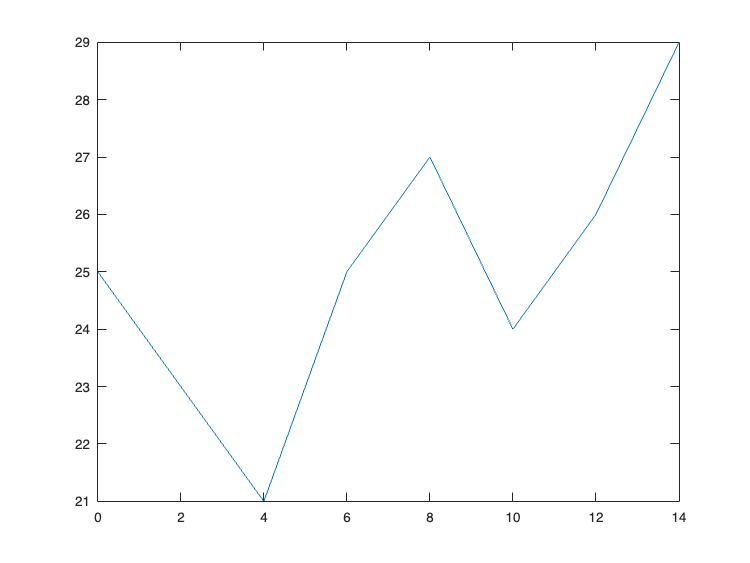

function [output] = recursion(input)


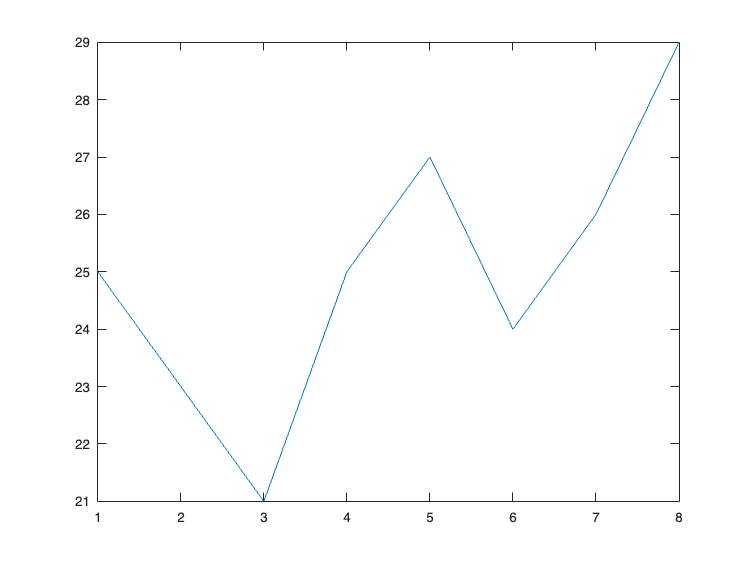

    % if (input satifies kill statement)
        output = input;

        return
    % else
        output = recursion(input); 
    % end

end

## 6 Structuring your code

In large programs or scripts it can be useful to modularize, or separate your code at specific *’landmark’* points to keep overview over the code. A useful command here is: 

`    %% followed by a space will make a new section.` 

The active section is specifically highlighted by MATLAB with a yellow background and can also be executed individually by choosing *¨Evaluate current section¨* from the context menu. 

A further way to keep overview over (especially nested) code is to ’*indent*’ your code, which means to put those code lines that are inside a loop or an if-clause to the right such that all code on the same ’*level*’ will be vertically left aligned. This helps especially if you have several dierent loops and if-clauses. This can be done by selecting ¨Indent Decrease¨ or ¨Indent increase¨ from the editor menu bar. You can automatize the code indentation by marking your code with the mouse and selecting ¨*Indent smart*¨.

## 7 Plotting

### 7.1 Basic plot tools

One of the biggest advantages of MATLAB is its ability to handle large quantities of data and displaying it in graphical form. Plotting is one of the multiple ways to graphically display data.

- `figure` opens a new figure window

- `plot(y)` plots the elements within the vector y as a function of their index into the current figure. 

- `plot(x,y)` plots each element of y as a function of the corresponding element in x. x needs to be unique and of the same size as y.

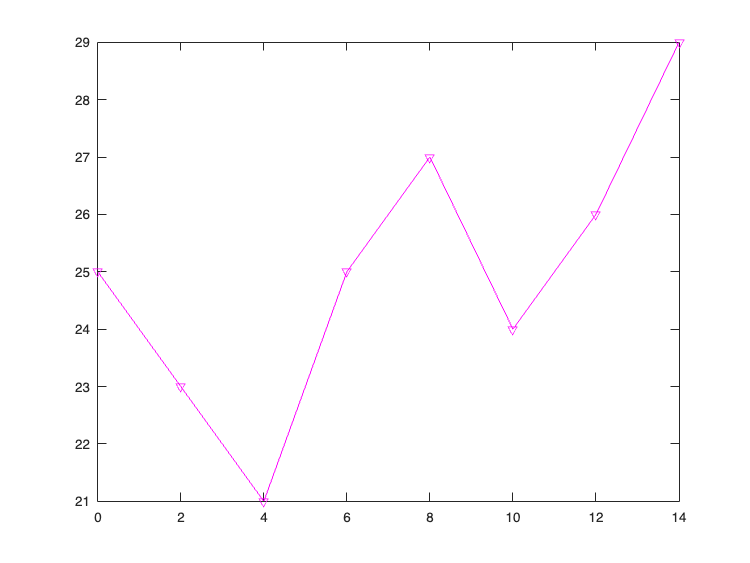

x = 0:2:14;

y = [25 23 21 25 27 24 26 29];

figure;
plot(x, y)
% pay attention to the x-axis
plot(y)

The plot command can be extended with a third input argument, which is a *string* (i.e., in high quotations `''`) specifying the **color**, the **symbol** (i.e., marker) and the **line style** that it should use.

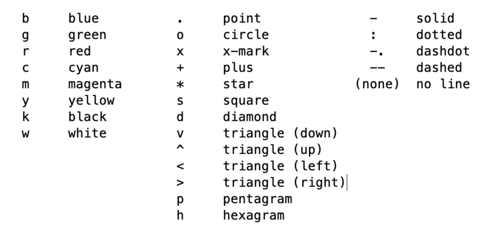

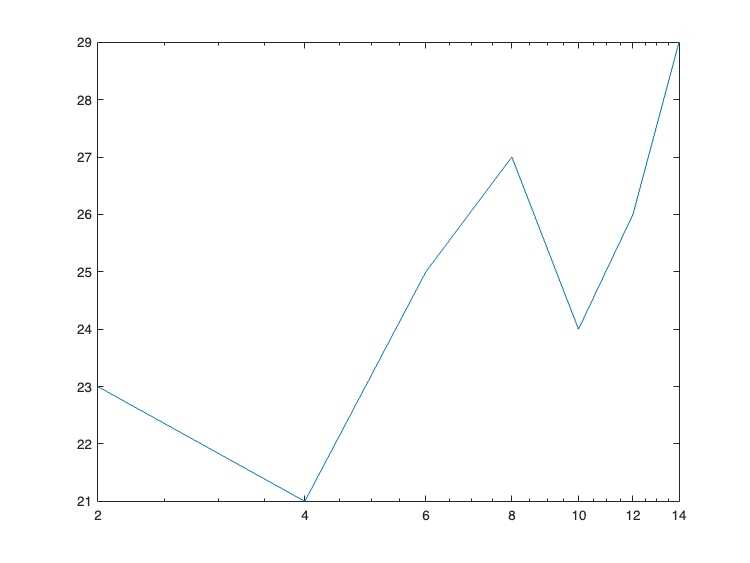

color = "m";

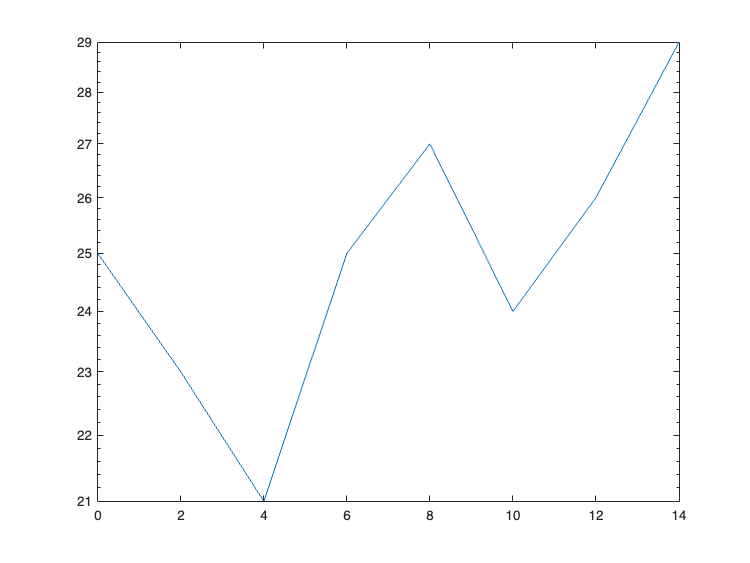

symbol = "v";
line_style = "-";


% plots circles around each datapoint and connects them
plot(x, y, color + symbol + line_style)

### 7.2 More basic plot commands

You can manipulate many of these figure properties also using the graphical user interface (GUI) in the plot figure. In the GUI, MATLAB distinguishes between the ’figure’ (the background of the plot) and the ’axes’ (the foreground, the plot data/curve).

**Logarithmic plotting**

% on the x-axis
semilogx(x, y);
% on the y-axis
semilogy(x, y);
% on both x- and y-axis
loglog(x, y);

**Limits of axis**

setting the limits of x and y-axis to display

xmin = 0; xmax = 1; ymin = 0; ymax = 1;
axis([xmin xmax ymin ymax]);

setting the limits of x- and y-axis exactly fitting to the curve

axis tight;

**Add a grid to the plot**

grid on;

**Labels**

% on the x-axis
xlabel('x-label');

% on the y-axis
ylabel('y-label');

**Descriptions**

place a title to your figure using a string (LaTeX-interpretable)

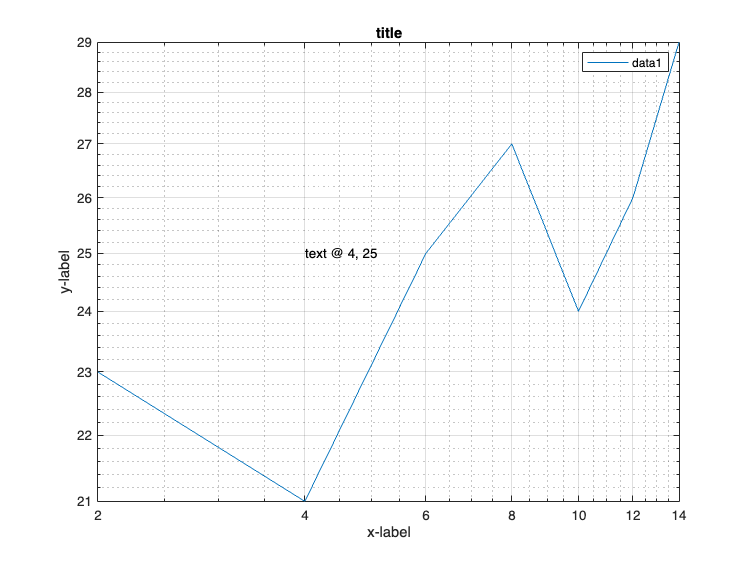

title('title');

place any text as a string at any position within the plot

xpos = 4; ypos = 25;
text(xpos, ypos, 'text @ 4, 25');

add a legend with several strings

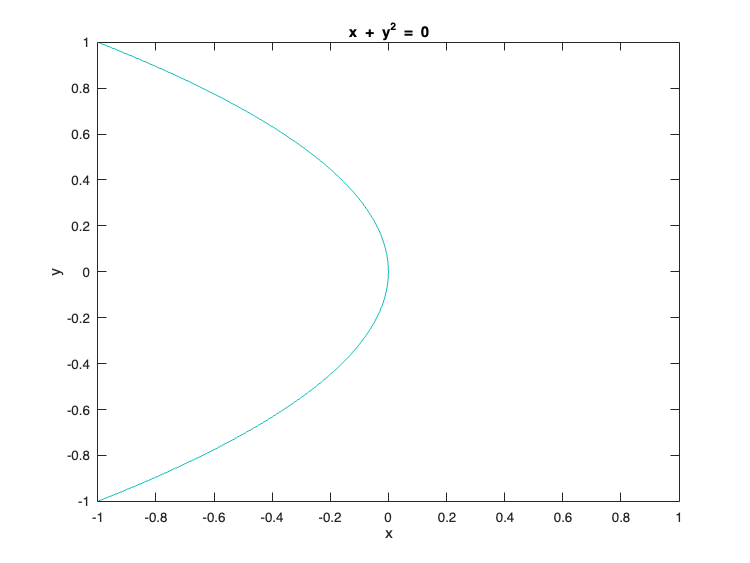

legend;

### 7.3 Plotting mathematical functions

The command `ezplot` allows to plot mathematical functions. `ezplot` will plot an equation written in standard notation with `x` and `y` as variables. This means that the function equation must be transformed such that all terms are on one side and the other side equals 0. In addition, this standard notation needs to be given as a string. 

By default `ezplot` plots the function for x-values between -2pi < x < 2pi.

If you want to plot over another range of x-values, the second argument of `ezplot` can be used to define such a dierent range of x-values to plot.

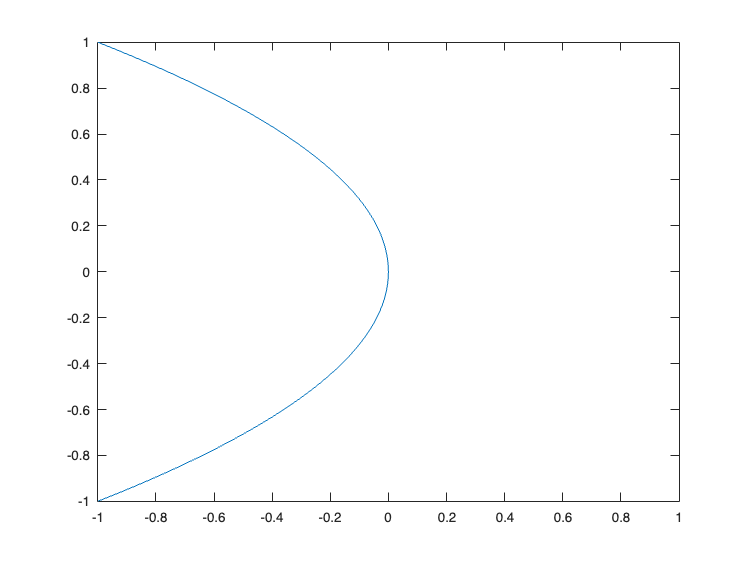

func = 'x + y^2';

figure;
ezplot(func, [-1, 1])

The use of `ezplot` is deprecated in new MatLab versions. Use the `fplot` or `fimplicit `function instead.

fimplicit(@(x, y) x + y^2, [-1, 1])

### 7.4 Plotting several curves in the same figure

By default MATLAB will delete and overwrite an old plot every time the plot command is used. 

`    hold on` 

will toggle MATLAB to keep all preceding plots in the figure. 

`    hold off` 

will toggle MATLAB to go back to default mode. When a new plot is added to the former plot(s), axes limits will change automatically to guarantee visibility of all data.

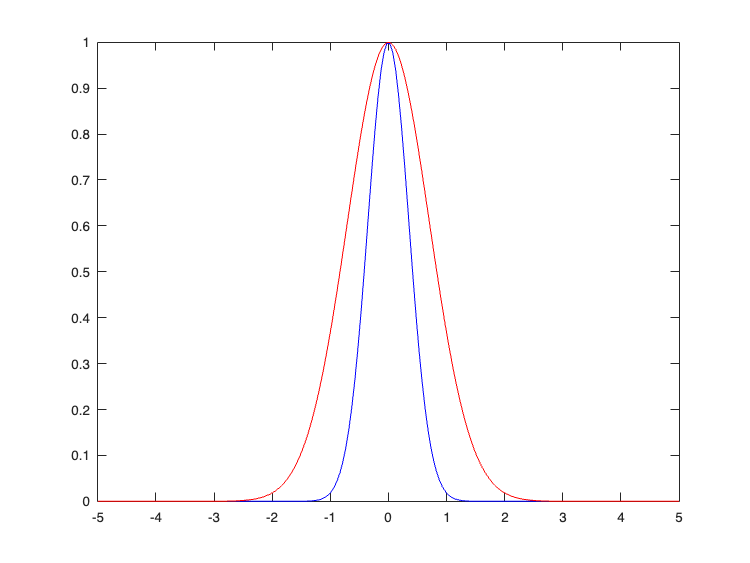

n = linspace(-5, 5, 200);

figure;
plot(n, exp(-(n).^2/0.5^2), 'b');


hold on;
plot(n, exp(-(n).^2/1^2), 'r')

### 7.5 Multiple plots

#### 7.5.1 The `subplot` command

Sometimes it is useful to have several plots within one figure side-by-side. This can be realized with the command `subplot`. `subplot` oers to display multiple graphs in the same figure in a matrix-style fashion. The general form of this command is

    `subplot(m, n, p)`

whereas m is the number of plot rows, n is the number of plot columns and p is the currently active plot, i.e., that plot where MATLAB will display data next. The figure therefore is broken up into an m x n matrix and will activate the pth ’axis’ element. If an output variable is assigned to the command subplot, MATLAB will return the handle of the pth axis element. Note that MATLAB now (for some reason) counts the subplots row-by-row and not (as we learned from the linear index notation of a matrix) column-by-column.

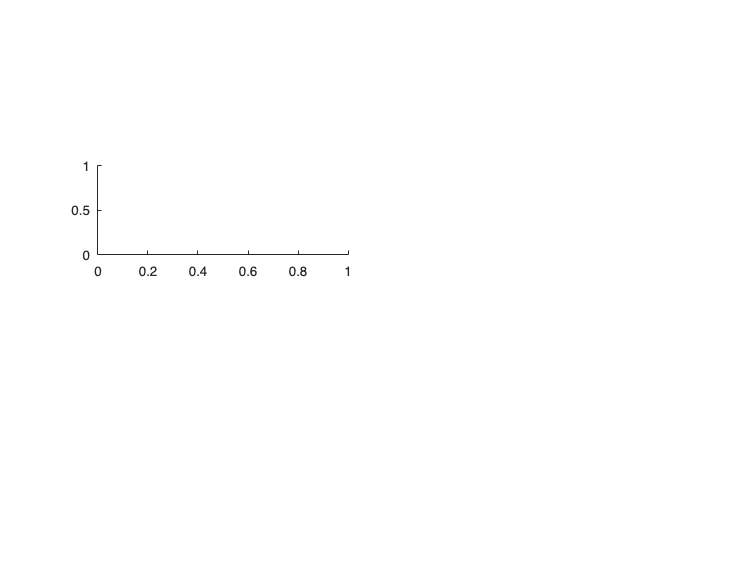

figure;
subplot(4, 2, 3);

The subplot command can also be expanded by using a vector as the third element. A vector controls whether two or several of these subplots should be merged.

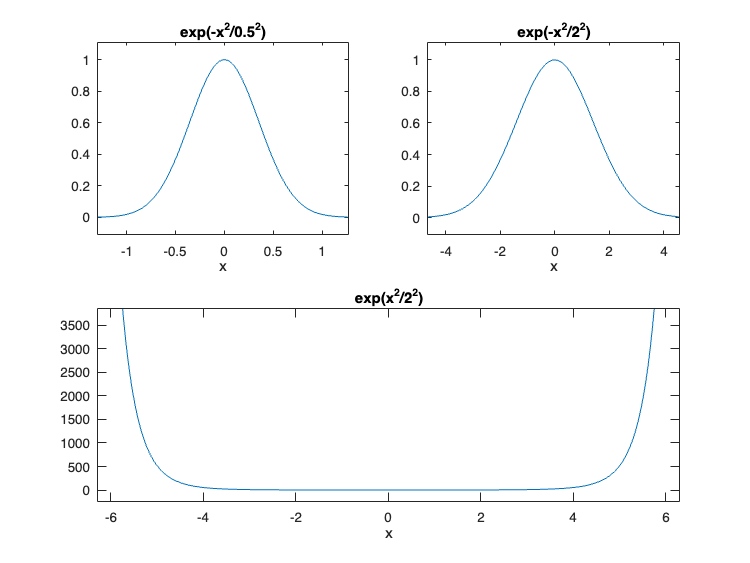

figure;
subplot(2, 2, 1);
ezplot('exp(-x.^2/0.5^2)');

subplot(2, 2, 2);
ezplot('exp(-x.^2/2^2)');

subplot(2, 2, 3:4);
ezplot('exp(x.^2/2^2)')

#### 7.5.2 Two different y-axes in the same plot

Plotting two data sets into one graph is possible with the command `hold on`. The key thing here is that with `hold on` the two data sets are plotted into the same y-axis, such that their absolute values are directly comparable. Sometimes, however, you may want to plot two data sets with different physical units and very different ranges of values within the same graph. Usually, then you don’t want to compare their absolute numerical values directly, but you want to show that the two data sets are of similar shape. The command

    `plotyy(x1, y1, x2, y2)`

is made exactly for this plots y1 versus x1 with y-axis labeling on the left and plots y2 versus x2 with a second y-axis labeling on the right.

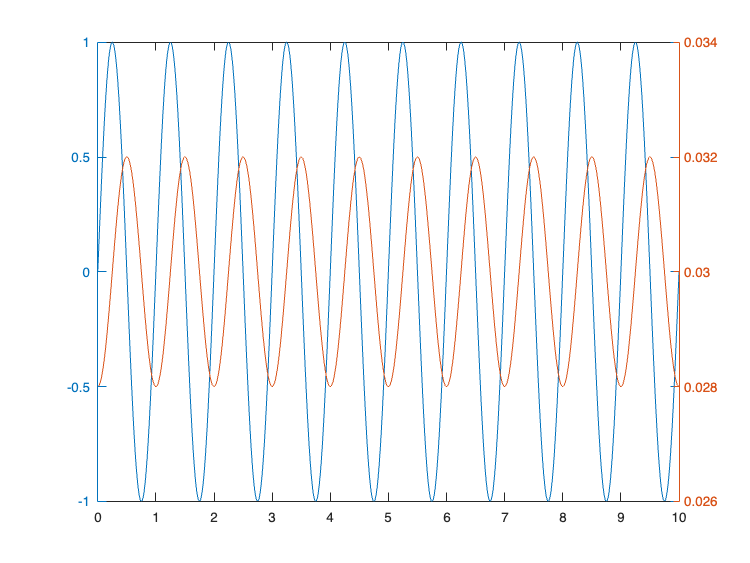

x = 0:1/1000:10;
y1 = sin(2*pi.*x);
y2 = sin(2*pi .* x - pi/2) .* 0.002 + 0.03;

figure;
plotyy(x, y1, x, y2); 

`plotyy` is not recommended in newer versions of MATLAB. Instead with appropriate code changes use the `yyaxis` function instead.

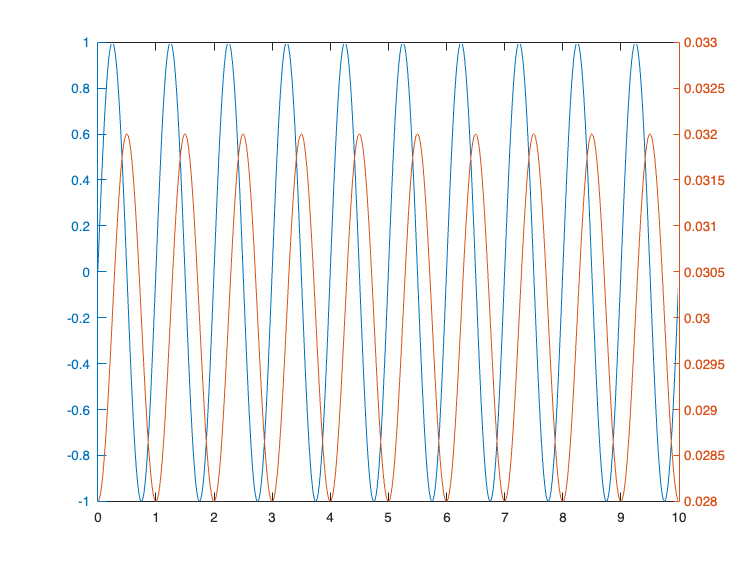

figure;
yyaxis left;
plot(x, y1)

yyaxis right;
plot(x, y2)

### 7.6 Appearance manipulation after plotting

MATLAB also offers free manipulation of figure, axes, and graphical objects by accessing the so-called ’*handles*’. This means that if an output variable is assigned to the plot-commands, such as plot or line, that variable represents a handle to the graphical object and can be used to address the appearance of the respective object. This can be used to change the color, increase the line width or change the marker symbol and many more properties of the respective object. The command to set the appearance of a property is

    `set(handle, 'property1', value1, 'property2', value2, ...);`

whereas handle is the handle variable. The respective property needs to be given as a string and must exactly match the property name that MATLAB has internally assigned to it. 

You can find how the property name is spelled by right-clicking on the object you want to manipulate with the mouse and choosing "Property editor" -> "More properties". The value can either be a number, a vector or a string, depending on the property you want to change. Which one it is, you can also find in the property editor.

x = -20:0.1:20;
sinc = sin(x)./x;

figure;
hold on;

line_graph = line(x, sinc, 'Color', 'r')

line_graph =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-20 -19.9000 -19.8000 -19.7000 -19.6000 -19.5000 -19.4000 -19.3000 -19.2000 -19.1000 -19 -18.9000 -18.8000 -18.7000 -18.6000 -18.5000 -18.4000 -18.3000 -18.2000 -18.1000 -18 -17.9000 -17.8000 -17.7000 -17.6000 … ] (1×401 double)
              YData: [0.0456 0.0436 0.0411 0.0382 0.0348 0.0311 0.0270 0.0226 0.0179 0.0130 0.0079 0.0027 -0.0026 -0.0080 -0.0133 -0.0185 -0.0236 -0.0285 -0.0332 -0.0376 -0.0417 -0.0454 -0.0487 -0.0516 -0.0539 -0.0558 -0.0570 -0.0578 … ] (1×401 double)
              ZData: [1×0 double]

  Show 

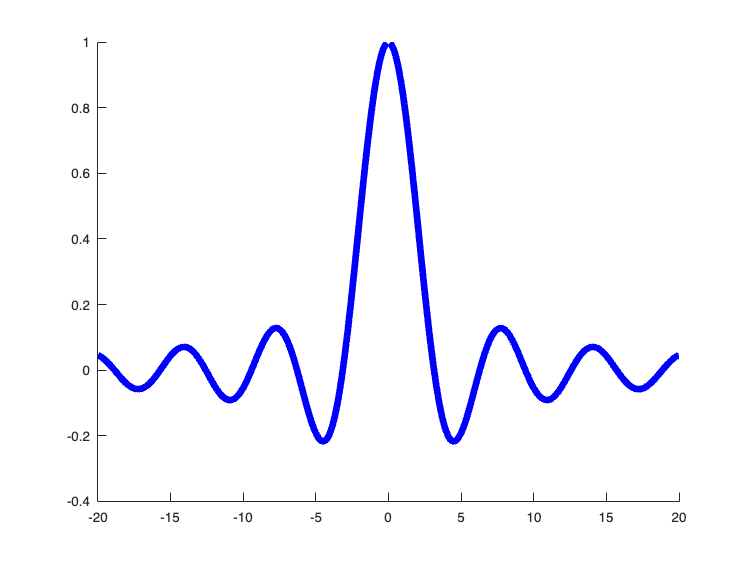

set(line_graph, 'Color', 'b', 'LineWidth', 5)

Another way to find what is the current value of a property is to use the command `get(handle,’property’)` This will output the present value in its correct data type.

get(line_graph, 'Color')

ans = 1×3
     0     0     1


Note that the `'Color'` property accepts both strings such as `'b'` using the set command, but internally MATLAB saves the property value as a 3-component vector denoting the red-green-blue (RGB) value. Each element of this 3-component vector is a number between 0 and 1 whereas 0 means lowest intensity and 1 denotes highest intensity. Plain red for example would be symbolized with `[1 0 0]`, i.e., highest intensity for red and no intensity for green and blue.

### 7.7 Hierarchical organisation of MATLAB plots

The examples so far have assigned handles as output variables when the respective plot-command was executed for example in the form

    `handle = plot(x);`

Sometimes handles cannot be created in this way or the user has forgotten to assign a handle to a graphical object. Luckily, MATLAB always creates handles in the background whenever any plot command has been called, even if the handle was not specifically assigned. But how to get access to these ’*hidden*’ handles? For getting the handle that you are looking for, you can make use of MATLABs hierarchical structure.

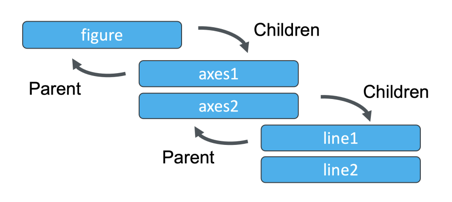

A `figure` object, i.e., the grey frame that is created when the command figure was used, is always a parent to all the objects that are created inside. The handle to the most recently created figure, or if you click and activate a specific figure, can be received by

    `fig_handle = gcf;`

whereas `gcf` stand for *"get current figure"*. Once you have such a parent handle, you can get the handle to the inside by asking MATLAB for its *"children"*. The next hierarchical level are the axes, which are inside a figure. This can be one object - and MATLAB will then return only one handle, or this can be several axes (for example if you have several subplots) and MATLAB will then return a vector with the handles of all these axes. You may then choose from this vector a specific entry to manipulate the appearence of a specific object. Note that MATLAB hereby uses reverse order, i.e., the most recently created object will have the first entry and the second-most recent the second entry etc. The same works with the current axes, using the command `gca`.

x = -20:0.1:20;

figure;
hold on;
plot(x, sin(x), 'b');
plot(x, cos(x), 'r');

plothandles = get(gca, 'Children')

plothandles =   2×1 Line array:

  Line
  Line


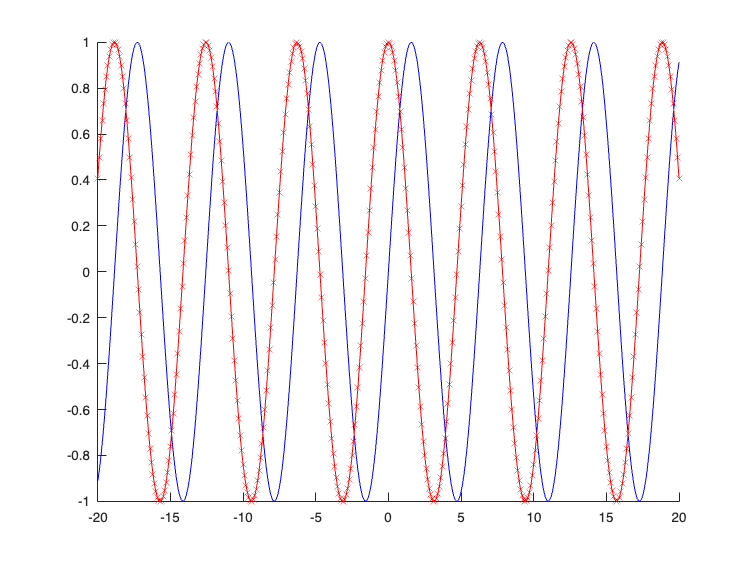

set(plothandles(1), 'Marker', 'x')

Dierent line plots within each axes are the children of the respective axes object. In the same way, if a handle to the parent hierarchical level object is needed, the handle can be obtained by

    `fig_handle = get(axes_handle, 'Parent')`

In principle, it is also possible to manually create a second y-axis with these control commands, just as the command `plotyy` would do.

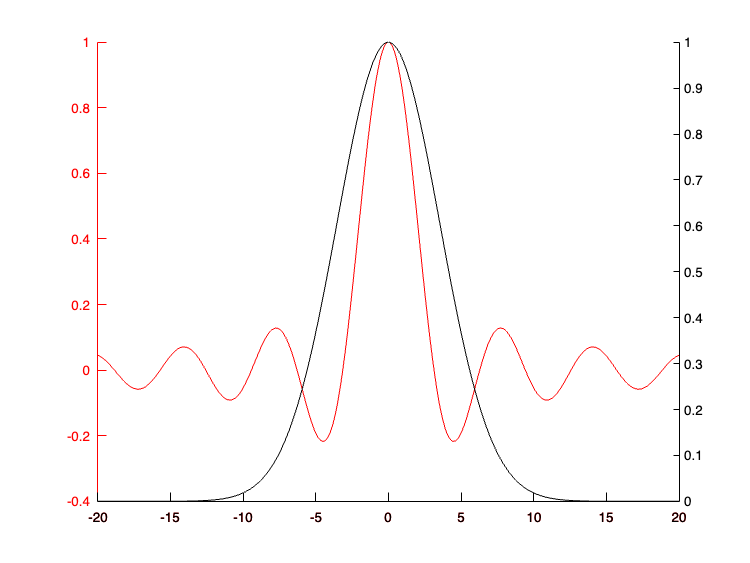

line_graph_gaussian =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-20 -19.9000 -19.8000 -19.7000 -19.6000 -19.5000 -19.4000 -19.3000 -19.2000 -19.1000 -19 -18.9000 -18.8000 -18.7000 -18.6000 -18.5000 -18.4000 -18.3000 -18.2000 -18.1000 -18 -17.9000 -17.8000 -17.7000 -17.6000 … ] (1×401 double)
              YData: [1.1254e-07 1.3201e-07 1.5473e-07 1.8121e-07 2.1206e-07 2.4796e-07 2.8971e-07 3.3821e-07 3.9452e-07 4.5983e-07 5.3553e-07 6.2320e-07 7.2463e-07 8.4190e-07 9.7737e-07 1.1337e-06 1.3140e-06 1.5218e-06 1.7611e-06 … ] (1×401 double)
              ZData: [1×0 double]

  Show 

x = -20:0.1:20;
sinc = sin(x)./x; 
gaussian = exp(-(x).^2/5^2);

figure; 
hold on; 
line_graph_sinc = line(x,sinc, 'Color', 'r');

axis_sinc = gca;
set(axis_sinc, 'XColor', 'r', 'YColor', 'r')

axis_gaussian = axes( ...
    'Position', get(axis_sinc, 'Position'), ...
    'XAxisLocation', 'bottom', ...
    'YAxisLocation', 'right', ...
    'Color', 'none', ...
    'XColor', 'k', ...
    'YColor', 'k' ...
);

line_graph_gaussian = line(x, gaussian, 'Color', 'k', 'Parent', axis_gaussian)

### 7.8 Plotting families of curves

The `plot` command also accepts matrices as input arguments. Every column is then plotted as a single line plot with a dierent color.

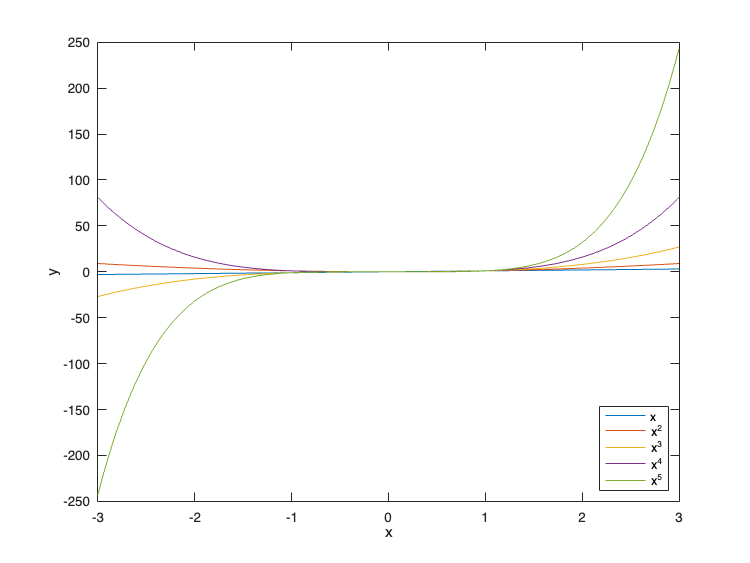

x = -3:0.01:3;

clear y;
y(:, 1) = x.^1;
y(:, 2) = x.^2;
y(:, 3) = x.^3;
y(:, 4) = x.^4;
y(:, 5) = x.^5;

figure;
plot(x, y);
xlabel('x');
ylabel('y');

legend('x', 'x^2', 'x^3', 'x^4', 'x^5', ...
    'Location', 'SouthEast')

### 7.9 3-dimensional plots

MATLAB provides several options for 3-dimensional plots. `plot3` is a simple command with the same methods for figure formatting. `plot3` needs three vectors of the same length as input values. These denote the x, y, and z-values to plot.

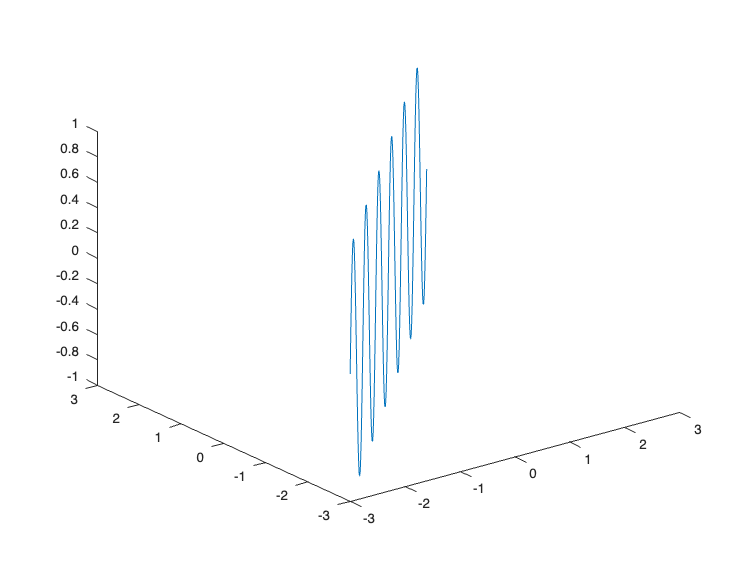

x = -3:0.01:3;
y = x;
z = sin(2*pi .* x);

figure;
plot3(x, y, z)

`surf` plots data of a matrix in a 3-dimensional surface plot. In contrast to the command `plot3`, `surf` does not necessarily need x- and y-variables. If they are omitted, `surf` outputs the matrix plot as a function of just the row- and column number of the matrix. If you want to customize your own x- and y-axis, you need to provide `surf` with x- and y-matrices of the same size as the matrix that you actually want to plot. This can be for example achieved with the function `meshgrid`. `surf` plots the matrix as a 3-dimensional ’*landscape*’, and additionally the height is reflected by a specific color code. High matrix values are yellow and orange and low matrix values are blue.

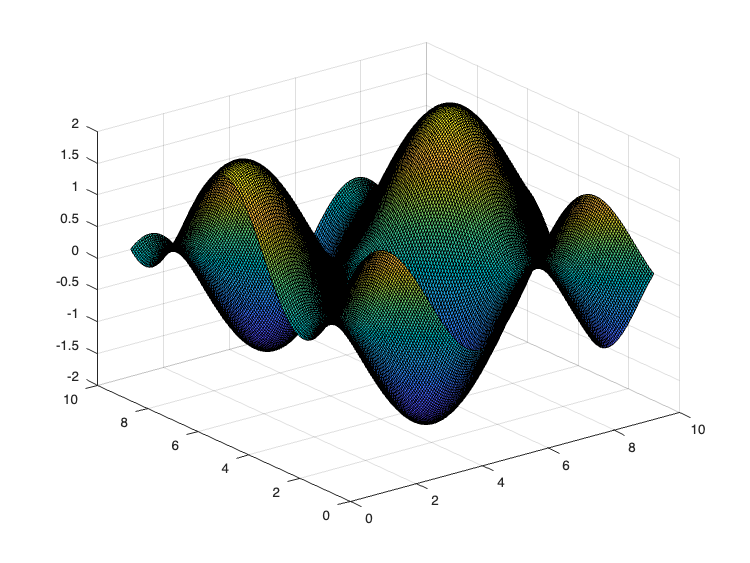

% 3D-cartesian coordinates
[X, Y] = meshgrid(1:0.05:10, 1:0.05:10);
Z = sin(X) + cos(Y);

surf(X, Y, Z)

The commands `image` and `imagesc` plot data of a matrix in a 2-dimensional color plot and interprets the ’*z-value*’ as color code. The output of `image` and `imagesc` can therefore be seen as about the same as with `surf` but with an angle from a bird’s eye view. `image` hereby uses a standard notation to assign colors to values: 0 and every value below 0 is being assigned dark blue and the value 64 and above is being assigned dark red. `imagesc` in contrast, scales the color assignment to the range of the values in the matrix being used as input. This means that the smallest value gets the color dark blue and the highest value gets the color dark red with a linear interpolation of color values in between.

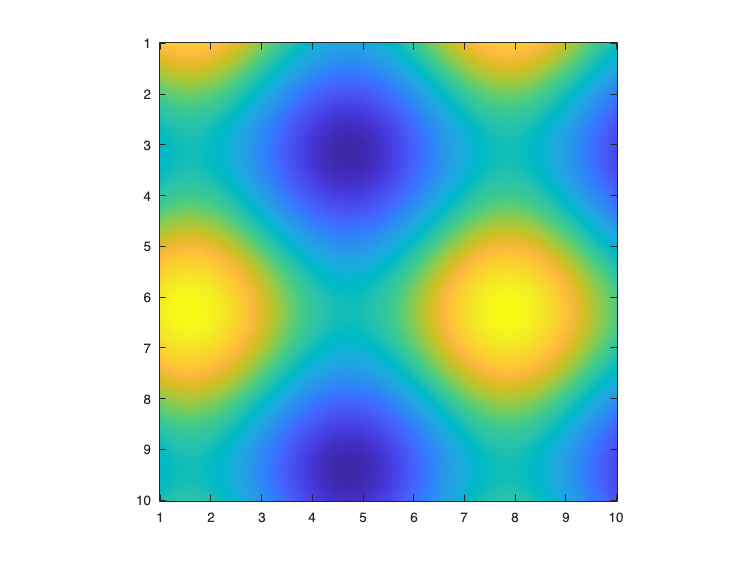

x = 1:0.05:10;
y = x;
Z = sin(x) + cos(y');

figure;
imagesc(x,y,Z);
axis square

`axis ij` und `axis xy` will arrange the origin of the coordinate system in the upper left or lower left corner, respectively. `colorbar` plots a color bar on the right side of the `imagesc` plot, such that the reader can see how the colors are being assigned to actual values.

### 7.10 Further plot options

MATLAB oers several more options to visualize data. Some more examples are:

**Bar plot**

`bar(vector)` will plot a bar plot from the data in the vector. `bar3` plots 3- dimensional bars.

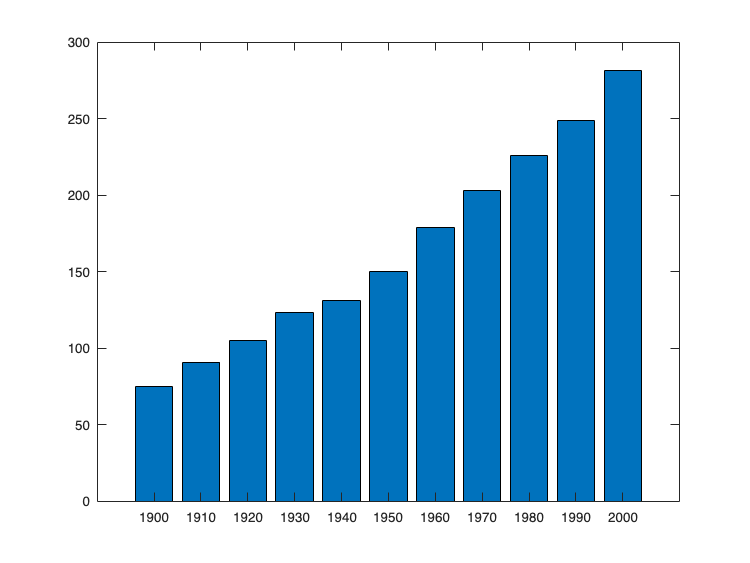

x = 1900:10:2000;
y = [75 91 105 123.5 131 150 179 203 226 249 281.5];

figure;
bar(x,y)

**Histograms**

`hist(vector, n)` will plot a histogram from the data in the vector with n bins.

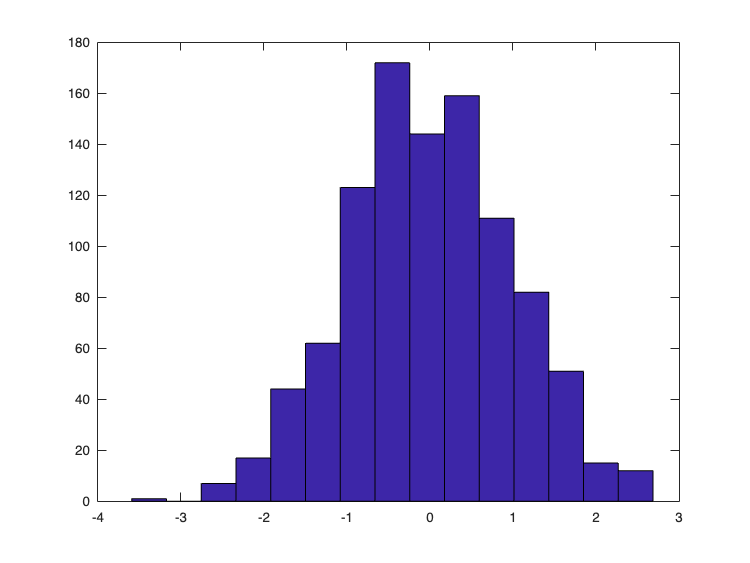

gaussian = randn(1000,1);

figure;
hist(gaussian,15);

**Boxplots**

For empirical biomedical data often boxplots are used. `boxplot(X)` produces box plots of the raw data in X (one box per column). A boxplot displays the data in boxes, whereas the edges of the box denote the 25th and 75th percentiles of the data and the horizontal line within the box denotes the median. This means that 50% of the data is located within the box. Whiskers extend to the most extreme data points (how long, that can be set as an option), and single outliers are being marked separately.

## 8 Control Flow

In programming there are multiple occasions where a segment of code is needed to be repeated a number of times or a segment should only run if a certain condition is met.

Just copy and pasting a code snippet several times is cumbersome and not ecient. Furthermore, it is easy to lose oversight over your code and such a method would be prone to errors, because if a modification in all duplicates of code is needed there is a large chance that the modification is forgotten in one of these duplicates. Each programming language has several ways to implement much more ecient methods to deal with these tasks.

### 8.1 Switch statements

The switch statement is one of the most basic method for segmenting code. As the name says the switch statement is a (flexilble) switch in your code where, depending on the initial condition, the work flow follows either one way or the other or a third one, etc. The syntax is

`    switch expression`

`        case expression`

`            statements`

`        case expression`

`            statements`

`        otherwise`

`            statements`

`    end`

Some more remarks:

- The number of cases that can be switched with this syntax is virtually infinite

- If dierent cases use the same set of statements it is possible to combine them by using `{ }` brackets.

`        case {2, 4, 6, 8, 12}`

- Switch-statements only separate different distinct options. It is not possible to place in the `expression` vectors or relationship operators, such as `<` or `>`.

- The `otherwise` statement is executed if the `expression` does not match any of the `cases`.

x = [12, 64, 24];
plotType = "one";

switch plotType
    case 'bar'
        bar(x)
        title('Bar Graph')
    case {'pie', 'pie3'}
        pie3(x)
        title('Pie Chart')
    otherwis'
        warning('Unexpected plot type. No plot created.');
end

Due to inability to use relationship (Boolean) operators, the `switch` statement is seldom used for algorithm development. Mostly, it will be used if user interaction is involved.

### 8.2 If statements

The if-statement is also used to segment pieces of code. It works based on a set of conditions that are in most cases logical expressions.

`    if (condition) `

`        statements `

`    elseif (condition) `

`        statements `

`    else `

`        statements `

`    end`

Some remarks here:

- A condition must be phrased as a `true` or `false` statement.

- If the condition is `true`, the expression within the if-block (here: `statements`) will be executed. If the condition is `false`, the expression will be skipped.

- If one of the condition is checked, the subsequent condition will only be checked if the former condition is `false`.

- The statement after the `else` keyword will only run if all other conditions are false.

moneyReceived = 50;
cost = 50;

if (moneyReceived > cost)
    profit = moneyReceived - cost;
else
    profit = 0;
end

profit

profit = 0

function [absolute] = absoluteValue(x)
    
    if (x > 0)
        absolute = x;
    elseif (x < 0)
        absolute = -x;
    else
        absolute = 0;
    end

end

value = 8;
absoluteValue(value)

ans = 8

#### 8.2.1 Nested If statements

If-statements are quite flexible and can be nested several times. Also here: Don’t forget the housekeeping! Indentation of lines helps to keep track of how your code works. Use it! The ’Smart indent’ button can automatically indent code for better clarity

### 8.3 Loops

A very common encounter in programming is that a piece of code needs to be executed several times. Just copy and pasting this piece of code the number of times it is necessary would in principle be a solution, however, this solution is cumbersome and in particular invites errors:

- If a small correction to the piece of code needs to be done after duplication, the small correction needs to be made in every single instance at the same place. 

- Such a programming code is hard to read for persons who have not written it, because it is hardly visible if there are small dierences between the duplicates or not.

A much better solution is to structure your code in loops, e.g., using `for`- and `while` loops. In these loops the code excerpt that is to be repeated is only written once and a running variable is used to control how often the code is being executed. The running variable can also be used to change variables from one loop iteration to the next, making the entire system very flexible and powerful. A possible flowchart realization of a loop may look as in Fig. 9.1. At the entry of a loop, a specific condition is being tested. If this condition is fulfilled the loop starts with the first iteration and the commands inside the loop are being executed. When all commands are done, the loop returns to the initial condition and tests this again. If the condition results still in ’TRUE’, the loop continues with the second iteration and so on. Only if the initial condition is being tested `FALSE` the loop is exited and the code outside and below the loop is being continued.

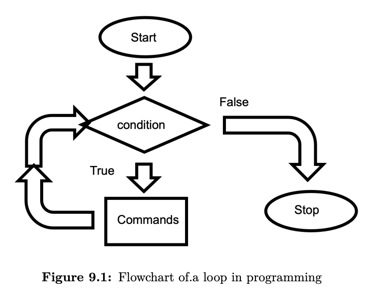

#### 8.3.1 While loops

The while-loop is an entry-controlled loop. This means that the condition is checked at the beginning of the loop. If the condition is false at the beginning, the loop will not be executed, even not a single time! The syntax is as follows:

`    while (condition)`

`        statements`

`    end`

Other computer languages such as C++, Java, C offer a `do...while` loop, where the loop is executed at least once regardless of the condition. MATLAB does not have this. Also here it is recommended to indent your code such that it is immediately obvious which parts are inside the loop and which parts are outside the loop. Very often a counter variable is being used for a while loop to control how many times the loop is being used. For that, the countervariable is initialized outside (e.g., `countervariable = 1;`) before the loop and then the condition contains a Boolean expression that tests the countervariable to a specific value (e.g., `while (countervariable <= 16);`), and the countervariable is modified inside the loop, e.g., counted upwards (e.g., `countervariable = countervariable + 1;`).

% The task is to go through a vector, and return all the positions of a particular
% value. This alternative uses a while-loop.
vector = [2, 4, 5, 3, 5, 2, 5];
value = 5;

counter= 1;
while (counter <= size(vector,2))
    if (vector(counter) == value)
        fprintf('found at location: %d; \n', counter);
    end
    counter = counter + 1;
end

found at location: 3; 
found at location: 5; 
found at location: 7; 


#### 8.3.2 For loops

`For`-loops in MATLAB appear significantly dierent than in any other programming language, but the concept is the same. The `for`-loop was designed with a specific number of iterations in mind. Therefore a loopvariable, or better loopvector is being used in the initial condition statement of the `for`-syntax and every specified element of the vector is being used subsequently from one iteration to the next. The special thing here is that in every loop-run the loopvariable is automatically increased by increment until the `endValue` is met. After that, the loop is executed. Therefore it is not necessary and may even create unwanted interferences if the loopvariable is being additionally increased inside the loop. 

Do not use a statement inside the for-loop where you count up the loopvariable! 

The syntax is as follows:

`    for loopvariable = startValue : increment : endValue`

`        statements;`

`    end`

Loops can easily also be used in a nested fashion, so you can use a loop inside of the loop. The signal flow will then continue to execute the inner-most loop until the condition of the inner-most loop is `FALSE` and then will start a new iteration in the next-outer loop.

% The task is to go through a vector, and return all the positions of a particular
% value. This alternative uses a for-loop.

vector = [2, 4, 5, 3, 5, 2, 5];
value = 5;

for counter = 1 : size(vector,2)
    if (vector(counter) == value)
        fprintf('found at location: %d; \n', counter);
    end
end

found at location: 3; 
found at location: 5; 
found at location: 7; 


#### 8.3.3 Break and Continue statements

In some cases, a loop must be exited before the predefined condition. This may be if a specific variable for example does not have the expected format or data type or an error occurs that should not immediately lead to terminating the entire program. The keyword `break` can be used to stop the current loop and return the next-outer loop or (if there is only one loop) to continue outside and below the loop.

In some other cases, the code in the loop should be skipped, but the loop should continue its operations. Use the keyword `continue` to do that. If the condition is met, any code below the continue will be skipped and a new iteration will be done.

#### 8.3.4 When to use while-loops and when to use for-loops

`For`-loops should be used if the number of iterations within the loop is known already at the entry of the loop. Examples: 

- If every element of a matrix or a vector should be tested or processed 

- If there is a finite number of cases that need to be iterated with the same code and that number is known. 

While-loops should be used if the number of iterations within the loop is unknown Examples: 

- Convergence of a series or of an array 

- Fit-Tasks that require a certain accuracy to be met

#### 8.3.5 Avoid loops

Computationally, loops are relatively expensive, i.e., time-consuming to execute, because the program needs to iteratively go through each loop iteration one after the other. It is much more ecient if the same operation can be done all at once, e.g., using a clever matrix multiplication, rather than using loops. The design of MATLAB often allows to avoid loops and therefore program much more eciently to use the computational resources. Therefore, whenever possible, try to avoid loops!

## 9 Boolean Operators

Boolean operators can be used in conditions within `if`-statements or `while`-statements. They either serve to compare different values or they serve to combine two or several conditions. The Boolean operators to compare are already known from section 3.1.3. However, each of these comparison Boolean operator has also a (less well-known) synomym:

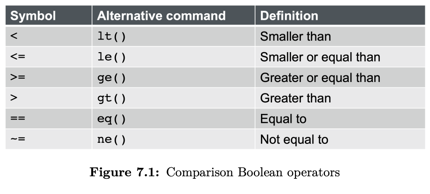

The Boolean operators to combine also have alternative commands:

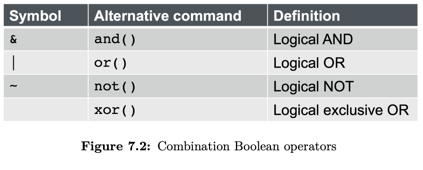

Boolean operators to combine are mostly used to combine two logical variables or expressions. These logical variables can only have two values, either "`1`" = `TRUE` and "`0`" = `FALSE`. For example, 

- the `and()` operator combines two input logical variables to a logical "`1`" only if both of these input variables are "`1`". If any of these input variables is "`0`", the `and()` operator outputs "`0`". 

- Similarly, the `or()` operator combines two input logical variables to a logical "`1`" if either the first or the second input variable is "`1`". 

- The `not()` operator inverts the logical input variable, such that a logical "`0`" becomes "`1`" and a logical "`1`" becomes "`0`". 

Fig. 7.3 shows the logical output to all combination Boolean operators.

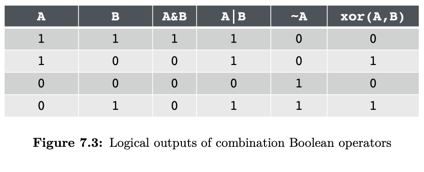

In addition to these logical operators, MATLAB offers logical operators for ’*shortcircuiting*’. Short-circuiting means the second operand (right hand side) is evaluated only when the result is not fully determined by the first operand (left hand side). Why this is useful can be seen in Fig. 7.3. For example, in the case of `A&B` , if `A` is already "`0`" = `FALSE`, the result of the operation `A&B` is in any case "`0`", no matter what logical value `B` has. Therefore, it is actually not necessary to evaluate if `B` is "`0`" or "`1`". If `A` is "`1`", the result of the operation `A&B` depends on the value of `B`, so `B` needs to be evaluated. The following operators do these short-circuits:

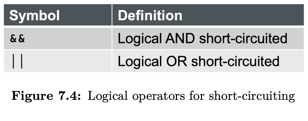

The short-circuiting behavior may save computational time for specific real-time applications.

### 9.1 Brackets do make a difference

Especially when using short-circuit Boolean operators it is really important to control that your signal flow creates the expected outcome. Use round brackets `()` to group multiple conditions in order to get expected results. Without any brackets, MATLAB evaluates the combined logical statement from left to right and stops evaluating (= short-circuits) if it finds that a further evaluation of the right side will not change the result.

%  here, the || short-circuits
1 && 1 || 0 && 0 

ans = logical
   1


 % same statement with brackets
(1 && 1 || 0) && 0

ans = logical
   0


### 9.2 Testing for Data Type

Sometimes, you will not exactly know in the runtime of the program what type of data type a specific variable may be. Therefore, it is useful to use logical ’*testing*’ functions, whose only purpose is to say whether or not a variable is a specific data type. MATLAB offers several functions to test variables for their data type or value. Much of the functionality is self-explanatory by its name:

x = 1i;

islogical(x)

ans = logical
   0


isnumeric(x)

ans = logical
   1


isinteger(x) % asdwd

ans = logical
   0


ischar(x)

ans = logical
   0


isempty(x)

ans = logical
   0


isnan(x)

ans = logical
   0


isa(x, 'char')

ans = logical
   0


isreal(x)

ans = logical
   0


isfloat(x)

ans = logical
   1


iscell(x)

ans = logical
   0


isstruct(x)

ans = logical
   0


## 10 Flow charts

Flow charts are used in programming to structure and plan a program before the actual coding using commands. Flow charts therefore serve also to document your coding, to think about simplifying the task that the program should solve, and they are operating system and programming language independent. Furthermore, they can also help in debugging your code. We will use flow charts especially for medium and higher complexity of coding, and to structure certain subtasks that the program should do. The respective building blocks of flow charts are:

- **Terminal**: The ellipse denotes Start, Stop and Pause in a flow chart.

                    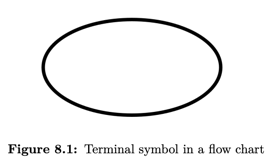

- **Input/Output**: A parallelogram indicates a building block where either input or output happens. Input could be the user pressing a key or inputting a specific word. An example for an output could be the displaying of the value of a specific variable via the screen or simply outputting a variable out of the function.

                    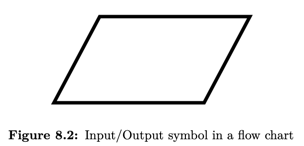

- **Processing**: A rectangle contains arithmetic operations such as addition, multiplication, subtraction, division and all other mathematical operations that work on the variables.

                    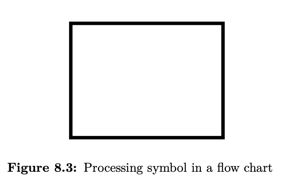

- **Decision**: A diamond stands for a decision point in the coding flow. Usually, the code splits here at least into two branches depending on a criterion that is evaluated at the decision point. This could be for example be done in an if-statement, a switch-statement, or (as we will see later) also as the starting point within a loop.

                     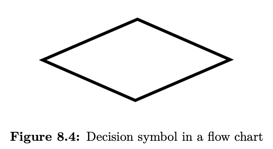

- **Connectors**: The circle denotes a connector symbol. Whenever your code comes back to a specific point when it was branched before, use a circle to symbolize the connection.

                      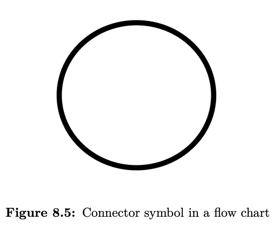

- **Flow arrows**: Arrows indicate the connection and the direction of the program flow. The usual direction is from top to bottom, which is the same as the final program later will be executed.

**Example**

A program should be written in which the user is being asked for two numbers. If the first number is higher, the smaller number should be outputted to the screen. If the second number is higher, the first number should be multiplied by two. In the end the current first number should be outputted on the screen.

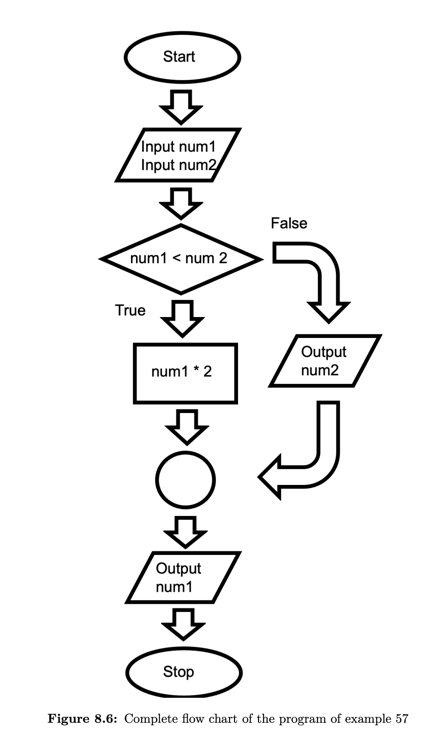

## 11 Cell and Struct Arrays

Sometimes it is useful to summarize data of dierent length or dierent data types into one variable. An example for this would be a patient data base that contains for each patient various data, such as name, telephone number, blood pressure data, photo, ... Vectors and matrices cannot handle such diverse data types within one variable. MATLAB oers for such applications two dierent overarching data types, cell arrays and struct arrays.

### 11.1 Cell arrays

Cell arrays are useful when the data type is the same, but the length is different. Cell arrays are initiated and called with curly brackets {}. They can also be used with different data types, however, whenever you want to put different data types into one variable, rather use struct arrays (see below).

**Example**

The variable `Euro_countries` should contain all country names of European countries. This can be done with a one-dimensional cell array:

Euro_countries{1} = 'The Netherlands';
Euro_countries{2} = 'Germany';
Euro_countries{3} = 'Denmark';

Similar to regular arrays, also matrices are possible, so let’s do this with world countries, whereas each row should denote a dierent continent, e.g., ’1’ = North America, ’2’ = Asia, '3' = Europe, ’5’ = Australia and Oceania.

World_countries{1,1} = 'USA';
World_countries{2,1} = 'China';
World_countries{5,1} = 'Marshal Islands';
World_countries{3} = Euro_countries;

### 11.2 Struct arrays

Struct arrays are useful to store many different data types within a single variable container systematically. This has advantages, e.g., if an entire database needs to be used as an input or output for a specific function: It can then just be input our output with one variable. 

Inside of this ’container’ variable, the data is structured (therefore the name struct) within different fields whose field names need to be defined. It is very flexibly possible to add and delete field names also later. Think of it as a form that contains fields with dffierent entries. The different fields and subfields of the struct array can be accessed with the dot operator ’.’. Note that struct arrays are accessed with round brackets, just as regular vectors

patient(1).name = 'Erwin Mueller';
patient(1).height = 1.75;
patient(1).weight = 70;
patient(1).insurance = false;

patient(2).name = 'Roswitha Meyer';

It is then very easy to display all saved items across all patients on the screen

patient.name

ans = 'Erwin Mueller'

ans = 'Roswitha Meyer'

MATLAB has several useful commands for cells and structs:

**Tests for Data Type**

test whether the variable is a cell

iscell(patient) 

ans = logical
   0


test whether the variable is a struct

isstruct(patient)

ans = logical
   1


test whether the field is part of a struct

isfield(patient, 'height')

ans = logical
   1


**Initialize a Data Type**

initialize a struct

person = struct('name', 'Max Mueller', 'height', 174, 'weight', 73, 'additional', false)

person = struct with fields:
          name: 'Max Mueller'
        height: 174
        weight: 73
    additional: 0


initialize a cell

cell(3)

ans = 3×3 cell array
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {0×0 double}


**Operations of Fields**

get structure field contents

% getfield(person, 'name')
person.('name')

ans = 'Max Mueller'

set structure field contents

% person = setfield(person, 'weight', 80)
person.('weight') = 80

person = struct with fields:
          name: 'Max Mueller'
        height: 174
        weight: 80
    additional: 0


get structure field names

fieldnames(person)

ans = 4×1 cell array
    {'name'      }
    {'height'    }
    {'weight'    }
    {'additional'}


order fields in a struct array

orderfields(person)

ans = struct with fields:
    additional: 0
        height: 174
          name: 'Max Mueller'
        weight: 80


remove field from struct

person = rmfield(person, 'additional')

person = struct with fields:
      name: 'Max Mueller'
    height: 174
    weight: 80


**Conversion between Data Types**

convert struct array to cell array

person_cell = struct2cell(person)

person_cell = 3×1 cell array
    {'Max Mueller'}
    {[        174]}
    {[         80]}


convert cell array to struct array

T(1,:) = {"highs",[44,38,46,43,48]};
T(2,:) = {"lows",[35,31,32,28,35]};
fields = [T{:,1}]

fields = 1×2 string array
    "highs"    "lows"


temps = T(:,2)

temps = 2×1 cell array
    {[44 38 46 43 48]}
    {[35 31 32 28 35]}


Tstruct = cell2struct(temps,fields)

Tstruct = struct with fields:
    highs: [44 38 46 43 48]
     lows: [35 31 32 28 35]


## 12 File I/O

MATLAB can save Plots (as FIG or TIF, JPG, PNG?) to disk using the saveas command. The current workspace, or specific variables from the workspace can be saved in a MAT-file using the command `save`. The command `open` opens a MAT or FIG file back into the current workflow.

What to do if the file that contains data to be used in MATLAB is just a plain text file? `textscan` reads in simple plain text into a cell array. If each word/digit should be accessed separately, you need to specify this with the respective format delimiter. These delimiters (for example `%s`, `%d` are the same as those that are already known from the command `sprintf`. To access a file that is not-MATLAB-generic, the commands `fopen` and `fclose` should be used. These commands create and close a ’file identifier’ variable that can be used similar as a handle can be used for figures or plots.

**Example: **Read in plain text file

fid = fopen('files/text', 'r')

fid = 23

text_in_file = textscan(fid, '%s')

text_in_file = 1×1 cell array
    {7×1 cell}


celldisp(text_in_file)

 
text_in_file{1}{1} =
 
You
 
 
text_in_file{1}{2} =
 
have
 
 
text_in_file{1}{3} =
 
woken
 
 
text_in_file{1}{4} =
 
the
 
 
text_in_file{1}{5} =
 
happy
 
 
text_in_file{1}{6} =
 
MatLab
 
 
text_in_file{1}{7} =
 
monster!
 


fclose(fid);

The reverse way, writing plain text into a text file (i.e., file output) can be done with the command `fprintf`. `fprintf` writes text into a simple plain text file. Also here format delimiters should be used if the content of a variable should be written as a text.

**Example: **Write a plain text file

result = 125;
timestring = '20181206';
fid_log = fopen([ ...
    '.' ...
    filesep ...
    'files/log_lottery' ...
    timestring ...
    '.txt' ...
], 'a');

fprintf(fid_log, 'The result is %s\n', num2str(result));

The indication ’a’ stands for append. This creates a new file if it was not yet created or just adds it to the end of the file if it is already existing.

### 12.1 Sound

For sound input and output MATLAB uses the functions `audioread` and `audiowrite`. You need to get and specify the sampling frequency (and the bit size) to get expected results.

[wave, fs] = audioread('files/mysoundfile.mp3')

wave = 466560×2
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 44100

sound(wave, fs)

### 12.2 Images

For image data use the functions `imread` and `imwrite`.

image = imread('files/myimage.jpg')

image = 1500×2000×3 uint8 array
image(:,:,1) =

    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  

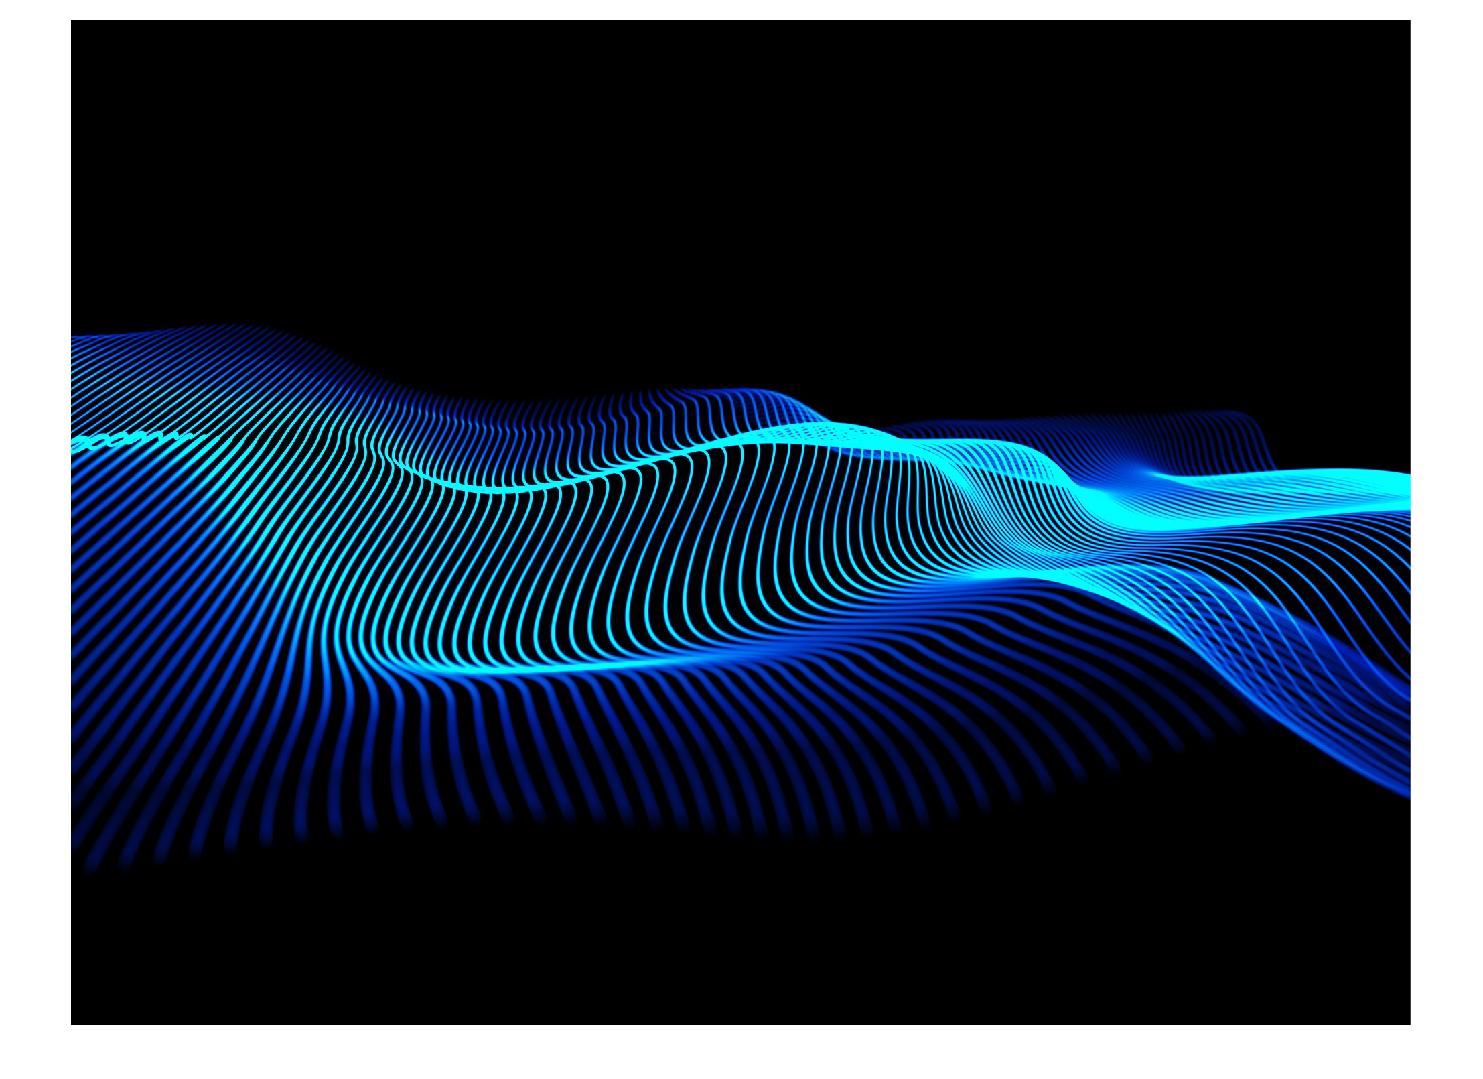

imshow(image)

### 12.3 Excel

`xlsread` and `xlswrite` load and save data from MATLAB into XLS-format as for example used by Microsoft Excel.

FILE = 'files/excel.xlsx';
SHEET = 'data';

% [NUM, TXT, RAW] = xlsread(FILE, SHEET)
readtable(FILE, Sheet=SHEET)

ans = 2×3 table
    Var1    Var2    Var3 
    ____    ____    _____

     12     NaN        20
    NaN      12     37653


readmatrix(FILE, Sheet=SHEET)

ans = 2×3
          12         NaN          20
         NaN          12       37653


readcell(FILE, Sheet=SHEET)

ans = 2×3 cell array
    {[  12]}    {'hello'}    {[         20]}
    {'moin'}    {[   12]}    {[01-Feb-2003]}


Hereby, `NUM` is the numerical data from the XLS-sheet, `TXT` is the optional text data and `RAW` is optional raw data from the XLS sheet. `FILE` specifies the file name and `SHEET` the sheet number. Similarly works the xlswrite command:

ARRAY = [1 2 3 4 5];
FILE = 'files/excel.xlsx';
SHEET = 'output';

% xlswrite(FILE, ARRAY, SHEET)
writematrix(ARRAY, FILE, Sheet=SHEET)